clear; clc; close all;

%% Parameter definieren (Quelle: Wikipedia)

G = 6.67430e-11;       % Gravitationskonstante 
M_sonne = 1.9884e30;   % Masse der Sonne in kg

abstand_erde_sonne=149.6*10^9;%[m]
radius_erde=6371*10^3;%[m]

% Erde
pos_erde = [abstand_erde_sonne, 0, 0];
T_Erde = 365.25*24*3600;    %[s]% 365.25=Umlaufzeit in Tagen
R_Erde = pos_erde(1);
M_erde  = 5.9722e24;   % Masse der Erde in kg

% Mars
pos_mars = [-227.9e9, 0, 0];
T_Mars = 687*24*3600;       %[s]% 687=Umlaufzeit in Tagen ca.
R_Mars = pos_mars(1);
M_mars  = 6.39e23;

%% 2. Berechnung der Winkelgeschwindigkeiten
% omega = 2 * pi / T
w_Erde = 2 * pi / T_Erde;
w_Mars = 2 * pi / T_Mars;

## Aufgabe 1: Plot: Modell des Sonnensystems

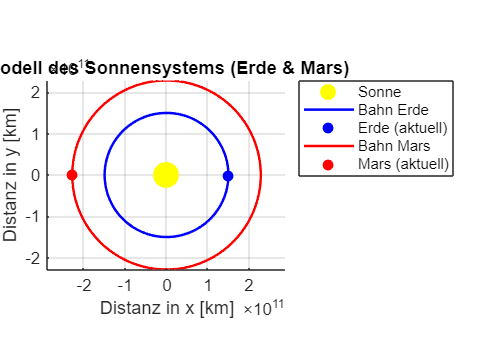

%Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:(1*24*3600):(730*24*3600); 

%% Berechnung der Bahnkurven (Trajektorien)
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

% Beschriftung
xlabel('Distanz in x [km]');
ylabel('Distanz in y [km]');
title('Modell des Sonnensystems (Erde & Mars)');
legend('Location', 'northeastoutside');

hold off;

% Parameter für die ode Funktion
tspan=[0 365*24*3600];

r0=[abstand_erde_sonne+radius_erde; 0; 0];
v0=[0;w_Erde*abstand_erde_sonne+15*10^3;0];
u0=[r0;v0];

## Nur mit Einfluss vom Gravitationsfeld Sonne

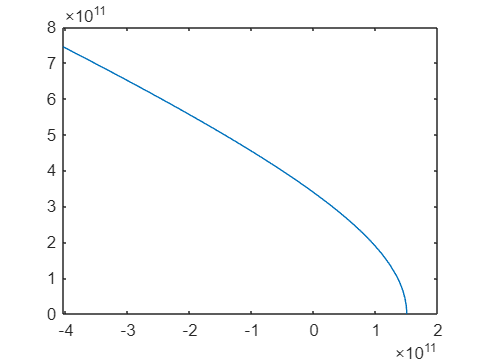

input_fuer_ode_sun=@(t,u) DGL_Sonne(t, u, G, M_sonne);
%das muss so gemacht werden, da ode45 nur zwei eingabewerte akzeptiert(t&u)
[t_erg_sun, u_erg_sun]=ode45(input_fuer_ode_sun,tspan,u0);
%t muss hier nur wegen syntaxvorgabe von ode45
plot(u_erg_sun(:,1), u_erg_sun(:,2))

## Mit Einfluss von Sonne, Erde und Mars

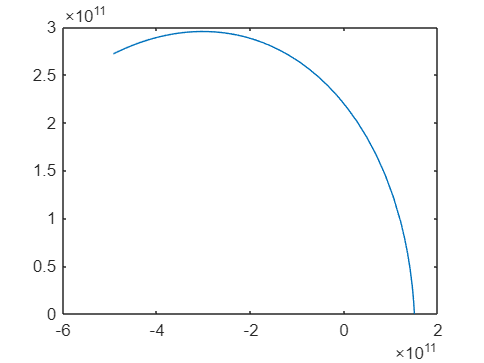

input_fuer_ode_sonnensystem=@(t,u) DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars);
%das muss so gemacht werden, da ode45 nur zwei eingabewerte akzeptiert(t&u)
[t_erg_so_sys, u_erg_so_sys]=ode45(input_fuer_ode_sonnensystem,tspan,u0);
%t muss hier nur wegen syntaxvorgabe von ode45
plot(u_erg_so_sys(:,1), u_erg_so_sys(:,2))

## Plot Zusammen:

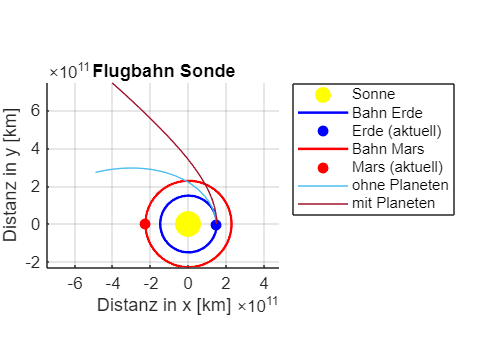

%Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:(1*24*3600):(730*24*3600); 

%% Berechnung der Bahnkurven (Trajektorien)
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

plot(u_erg_so_sys(:,1), u_erg_so_sys(:,2), 'DisplayName', 'ohne Planeten');
plot(u_erg_sun(:,1), u_erg_sun(:,2), 'DisplayName', 'mit Planeten');

% Beschriftung
xlabel('Distanz in x [km]');
ylabel('Distanz in y [km]');
title('Flugbahn Sonde');
legend('Location', 'northeastoutside');


hold off;







function du=DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars)
    
    du=zeros(6,1);   
    pos_sonne=[0; 0; 0];

    sonde_pos=u(1:3);
    v_sonde=u(4:6);

    % Berechnung der Bahnkurven (Trajektorien)
    % Erde
    x_Erde = R_Erde * cos(w_Erde * t);
    y_Erde = R_Erde * sin(w_Erde * t);
    
    % Mars
    x_Mars = R_Mars * cos(w_Mars * t);
    y_Mars = R_Mars * sin(w_Mars * t);
    
    pos_erde = [x_Erde; y_Erde; 0];
    pos_mars = [x_Mars; y_Mars; 0];

    %Gravitationsfeld der Sonne
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    %Berechnung Grevitationsfeld Erde
    r_vec_erde = sonde_pos - pos_erde;
    dist_erde = norm(r_vec_erde);
    g_erde = -G * M_erde * (r_vec_erde / dist_erde^3);

    % Berechnung Gravitationsfeldfeld Mars
    r_vec_mars = sonde_pos - pos_mars;
    dist_mars = norm(r_vec_mars);
    g_mars = -G * M_mars * (r_vec_mars / dist_mars^3);

    %% 4. Superposition (Vektoraddition)
    g_total = g_sonne + g_erde + g_mars;

    du=[v_sonde; g_total];
end

function du=DGL_Sonne(t, u, G, M_sonne)%nur mit Gravitationsfeld der Sonne

    pos_sonne = [0; 0; 0]; % Sonne im Ursprung des Koordinatensystems

    du=zeros(6,1);

    sonde_pos=u(1:3);
    v_sonde=u(4:6);
    
    %Gravitationsfeld der Sonne
    %Vektor von der Sonne zum Punkt
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    du=[v_sonde; g_sonne];%nachher g_total
end
